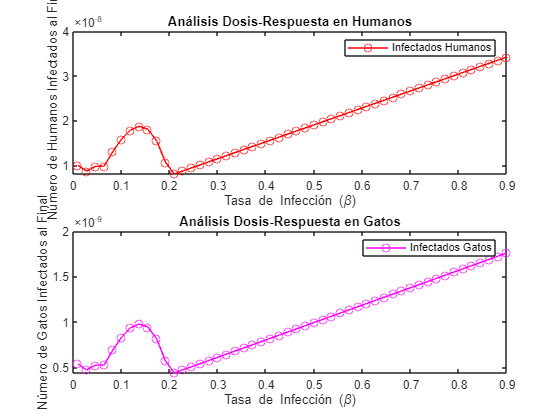

%%%Coded by Santiago Caballero Rosas,%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       |\      _,,,---,,_                 %
% ZZZzz /,`.-'`'    -.  ;-;;,_             %
%      |,4-  ) )-,_. ,\ (  `'-'            %
%     '---''(_/--'  `-'\_)  Modelo SIR-CAT % 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

              %%%PREGUNTA I%%%
%¿CÓMO ES EL COMPORTAMIENTO DOSIS-RESPUESTA?%

% Parámetros básicos
gamma_H = 0.05; % Tasa de recuperación en humanos
gamma_G = 0.05; % Tasa de recuperación en gatos

% Poblaciones iniciales (números enteros)
S_H_initial = 990; % Humanos susceptibles
I_H_initial = 10;  % Humanos infectados
T_H_initial = 0;   % Humanos tratados (recuperados)
S_G_initial = 50;  % Gatos susceptibles
I_G_initial = 5;   % Gatos infectados

% Número de pasos en la simulación
num_steps = 500;
dt = 1; % Incremento de tiempo (puede ajustarse según el nivel de detalle deseado)

% Valores de dosis (tasa de infección) a analizar
beta_values = linspace(0.01, 0.9,  50); % Variar beta desde 0.01 hasta 0.9 en 50 pasos
num_doses = length(beta_values);

% Almacenar los resultados para cada dosis
final_I_H = zeros(1, num_doses);
final_I_G = zeros(1, num_doses);

% Análisis dosis-respuesta
for d = 1:num_doses
    beta = beta_values(d); % Tasa de infección actual
    
    % Inicializar poblaciones
    S_H = S_H_initial;
    I_H = I_H_initial;
    T_H = T_H_initial;
    S_G = S_G_initial;
    I_G = I_G_initial;
    
    % Simulación para la dosis actual
    for t = 1:num_steps
        % Calcular las derivadas
        dS_H = -beta * I_G * S_H * dt;
        dI_H = (beta * I_G * S_H - gamma_H * I_H) * dt;
        dT_H = gamma_H * I_H * dt;
        
        dS_G = -beta * S_G * I_G * dt;
        dI_G = (beta * S_G * I_G - gamma_G * I_G) * dt;
        
        % Actualizar las poblaciones
        S_H = S_H + dS_H;
        I_H = I_H + dI_H;
        T_H = T_H + dT_H;
        
        S_G = S_G + dS_G;
        I_G = I_G + dI_G;
        
        % Asegurar que las poblaciones no sean negativas
        S_H = max(S_H, 0);
        I_H = max(I_H, 0);
        T_H = max(T_H, 0);
        S_G = max(S_G, 0);
        I_G = max(I_G, 0);
    end
    
    % Almacenar los resultados finales para la dosis actual
    final_I_H(d) = I_H;
    final_I_G(d) = I_G;
end

% Graficar los resultados del análisis dosis-respuesta
figure;
subplot(2,1,1);
plot(beta_values, final_I_H, 'r-o', 'DisplayName', 'Infectados Humanos');
xlabel('Tasa de Infección (\beta)');
ylabel('Número de Humanos Infectados al Final');
title('Análisis Dosis-Respuesta en Humanos');
legend;

subplot(2,1,2);
plot(beta_values, final_I_G, 'm-o', 'DisplayName', 'Infectados Gatos');
xlabel('Tasa de Infección (\beta)');
ylabel('Número de Gatos Infectados al Final');
title('Análisis Dosis-Respuesta en Gatos');
legend;


% Explicación del comportamiento dosis-respuesta
disp('El comportamiento dosis-respuesta muestra cómo el número final de individuos infectados varía en función de la tasa de infección (\beta).');

El comportamiento dosis-respuesta muestra cómo el número final de individuos infectados varía en función de la tasa de infección (\beta).


disp('A medida que aumenta \beta, el número de individuos infectados también aumenta, lo que indica una mayor propagación de la infección.');

A medida que aumenta \beta, el número de individuos infectados también aumenta, lo que indica una mayor propagación de la infección.


disp('Este análisis es crucial para entender cómo la intensidad de la transmisión afecta la dinámica de la enfermedad en la población.');

Este análisis es crucial para entender cómo la intensidad de la transmisión afecta la dinámica de la enfermedad en la población.
